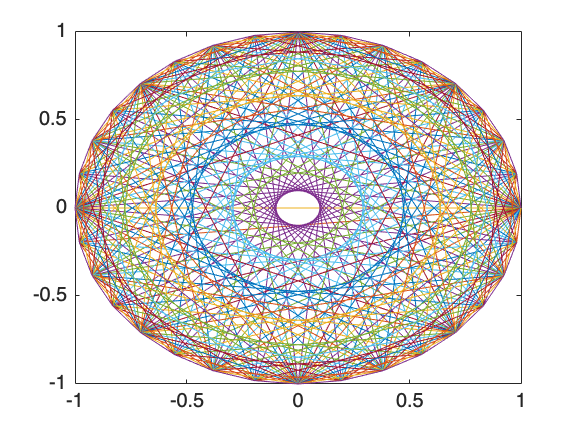

for k = 1:16
	plot(fft(eye(k+16)))
	axis([-1 1 -1 1])
	M(k) = getframe;
end

h = figure;
movie(h, M, 1, 5)

v = VideoWriter("test1.mp4", "MPEG-4");
v.FrameRate = 5.0;
open(v);
writeVideo(v, M);

close(v);